clear; clc; close all;

Set the random number generator to Mersenne Twister

rng(100,"twister")

Read the numeric 

x = readcell('companyData.xlsx')

x = 1775×37 cell array
    {'Date'       }    {'AAPL'    }    {'AEP'    }    {'AMT'     }    {'CLX'     }    {'COST'    }    {'CVX'     }    {'D'      }    {'DUK'     }    {'DXCM'   }    {'ECL'     }    {'ES'     }    {'EXR'     }    {'FDX'     }    {'GOOGL'   }    {'HAL'    }    {'HD'      }    {'HSY'     }    {'JPM'     }    {'KDP'    }    {'KIM'    }    {'LHX'     }    {'LIN'     }    {'MS'      }    {'MSFT'    }    {'NOW'       }    {'PCG'    }    {'PFE'    }    {'PLD'     }    {'RTX'     }    {'SCCO'   }    {'SHW'     }    {'SLG'    }    {'UNH'     }    {'V'       }    {'W'      }    {'XOM'     }
    {[22-Jan-2025]}    {[223.7600]}    {[97.4900]}    {[185.2900]}    {[158.7300]}    {[944.7000]}    {[156.4100]}    {[52.9300]}    {[108.8200]}    {[87.0900]}    {[241.6300]}    {[55.7900]}    {[150.0700]}    {[270.4300]}    {[200.0300]}    {[28.4800]}    {[410.1000]}    {[151.1200]}    {[262.8400]}    {[31.5000]}    {[22.2200]}    {[220.0600]}    {[442.6000]}    {[     136]}    {[446.2

Achieve the company's name by getting all the name of the first column

companyNames = x(1, 2:end)

companyNames = 1×36 cell array
    {'AAPL'}    {'AEP'}    {'AMT'}    {'CLX'}    {'COST'}    {'CVX'}    {'D'}    {'DUK'}    {'DXCM'}    {'ECL'}    {'ES'}    {'EXR'}    {'FDX'}    {'GOOGL'}    {'HAL'}    {'HD'}    {'HSY'}    {'JPM'}    {'KDP'}    {'KIM'}    {'LHX'}    {'LIN'}    {'MS'}    {'MSFT'}    {'NOW'}    {'PCG'}    {'PFE'}    {'PLD'}    {'RTX'}    {'SCCO'}    {'SHW'}    {'SLG'}    {'UNH'}    {'V'}    {'W'}    {'XOM'}


featureNames = x(2:end,1)

featureNames = 1774×1 cell array
    {[22-Jan-2025]}
    {[21-Jan-2025]}
    {[17-Jan-2025]}
    {[16-Jan-2025]}
    {[15-Jan-2025]}
    {[14-Jan-2025]}
    {[13-Jan-2025]}
    {[10-Jan-2025]}
    {[08-Jan-2025]}
    {[07-Jan-2025]}
    {[06-Jan-2025]}
    {[03-Jan-2025]}
    {[02-Jan-2025]}
    {[31-Dec-2024]}
    {[30-Dec-2024]}
    {[27-Dec-2024]}


Extract data

x = x(2:end, 2:end)

x = 1774×36 cell array
    {[223.7600]}    {[97.4900]}    {[185.2900]}    {[158.7300]}    {[944.7000]}    {[156.4100]}    {[52.9300]}    {[108.8200]}    {[87.0900]}    {[241.6300]}    {[55.7900]}    {[150.0700]}    {[270.4300]}    {[200.0300]}    {[28.4800]}    {[410.1000]}    {[151.1200]}    {[262.8400]}    {[31.5000]}    {[22.2200]}    {[220.0600]}    {[442.6000]}    {[     136]}    {[446.2000]}    {[1.1248e+03]}    {[16.4400]}    {[26.0100]}    {[115.1300]}    {[124.3800]}    {[96.3500]}    {[357.7400]}    {[67.1900]}    {[519.7200]}    {[323.5600]}    {[47.7500]}    {[109.5300]}
    {[222.6400]}    {[97.8100]}    {[189.9300]}    {[159.9900]}    {[947.7300]}    {[158.2400]}    {[55.9100]}    {[110.7700]}    {[86.3200]}    {[241.0700]}    {[58.2300]}    {[151.9100]}    {[275.5700]}    {[199.6300]}    {[29.5300]}    {[418.4300]}    {[153.5700]}    {[263.0300]}    {[31.7100]}    {[22.5000]}    {[222.8600]}    {[442.4600]}    {[137.3000]}    {[428.5000]}    {[1.0968e+03]}    {[17.3000]}

x = cell2mat(x)

x = 1.0e+03 *

    0.2238    0.0975    0.1853    0.1587    0.9447    0.1564    0.0529    0.1088    0.0871    0.2416    0.0558    0.1501    0.2704    0.2000    0.0285    0.4101    0.1511    0.2628    0.0315    0.0222    0.2201    0.4426    0.1360    0.4462    1.1248    0.0164    0.0260    0.1151    0.1244    0.0963    0.3577    0.0672    0.5197    0.3236    0.0478    0.1095
    0.2226    0.0978    0.1899    0.1600    0.9477    0.1582    0.0559    0.1108    0.0863    0.2411    0.0582    0.1519    0.2756    0.1996    0.0295    0.4184    0.1536    0.2630    0.0317    0.0225    0.2229    0.4425    0.1373    0.4285    1.0968    0.0173    0.0266    0.1173    0.1258    0.0987    0.3615    0.0672    0.5250    0.3236    0.0486    0.1115
    0.2300    0.0973    0.1904    0.1603    0.9432    0.1615    0.0553    0.1093    0.0844    0.2374    0.0579    0.1506    0.2751    0.1976    0.0299    0.4094    0.1529    0.2592    0.0316    0.0223    0.2182    0.4360    0.1379    0.4290    1.0715    0.0170   

Create and train Self-Organizing Map (SOM)

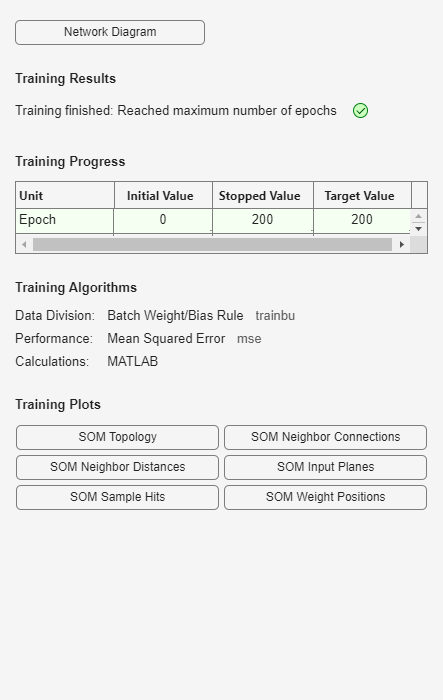

net = selforgmap([5 5]); 
[net,tr] = train(net,x);

Visualize SOM

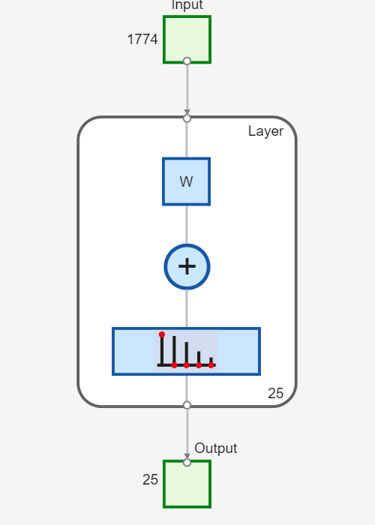

view(net);

 The network output will be a 393x37 matrix, where each ith column represents the jth cluster for each ith input vector with a 1 in its jth element

y = net(x);

The function `vec2ind` returns the index of the neuron with an output of 1, for each vector. The indices will range between 1 and 25

classes = vec2ind(y);

`plotsomtop` plots the SOM topology of 25 neurons positioned in an 5x5 hexagonal grid.

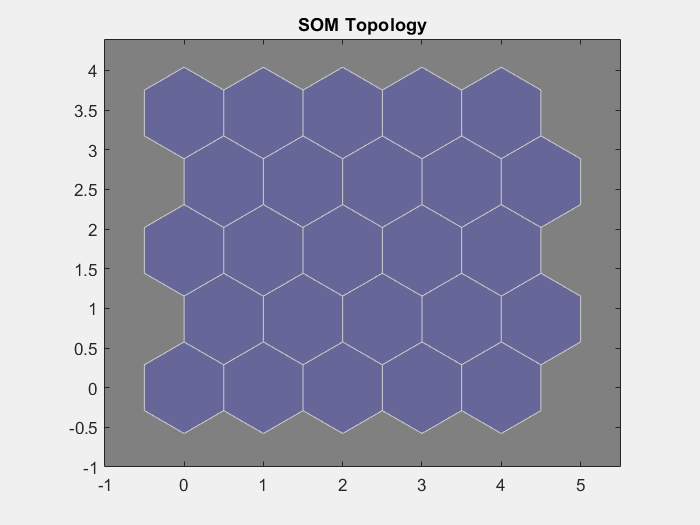

plotsomtop(net);

% Display mappings
for i = 1:numel(companyNames)
    fprintf('Company: %-20s → Neuron Index: %d\n', companyNames{i}, classes(i));
end

Company: AAPL                 → Neuron Index: 23
Company: AEP                  → Neuron Index: 11
Company: AMT                  → Neuron Index: 3
Company: CLX                  → Neuron Index: 7
Company: COST                 → Neuron Index: 25
Company: CVX                  → Neuron Index: 13
Company: D                    → Neuron Index: 16
Company: DUK                  → Neuron Index: 11
Company: DXCM                 → Neuron Index: 17
Company: ECL                  → Neuron Index: 8
Company: ES                   → Neuron Index: 16
Company: EXR                  → Neuron Index: 13
Company: FDX                  → Neuron Index: 4
Company: GOOGL                → Neuron Index: 13
Company: HAL                  → Neuron Index: 21
Company: HD                   → Neuron Index: 10
Company: HSY                  → Neuron Index: 14
Company: JPM                  → Neuron Index: 18
Company: KDP                  → Neuron Index: 21
Company: KIM                  → Neuron Index: 21
Company: LHX            

These are 21 companies at the same spot (index 24) . First, we find indices where the neuron index is 24.

fprintf('Companies at Neuron Index 24:\n');

Companies at Neuron Index 24:


idx24=find(classes ==24);
for i = 1:prod(size(idx24))
    fprintf('%s,', companyNames{idx24(i)});
end

MSFT,

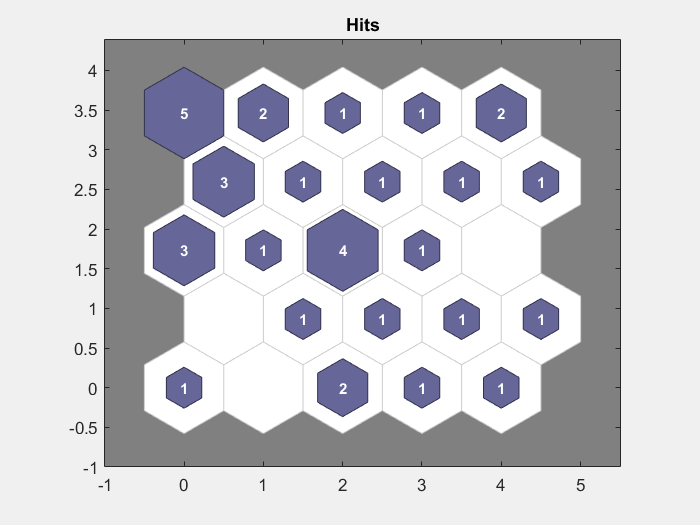

plotsomhits(net, x);

`There are 21 companies:AAPL,MSFT,GOOGL,COST,HSY,KDP,CVX,HAL,JPM,MS,V,UNH,FDX,LHX,ECL,SHW,SCCO,PLD,EXR,DUK,AEP`

`plotsomnc` shows the neuron neighbor connections. Neighbors typically classify similar company

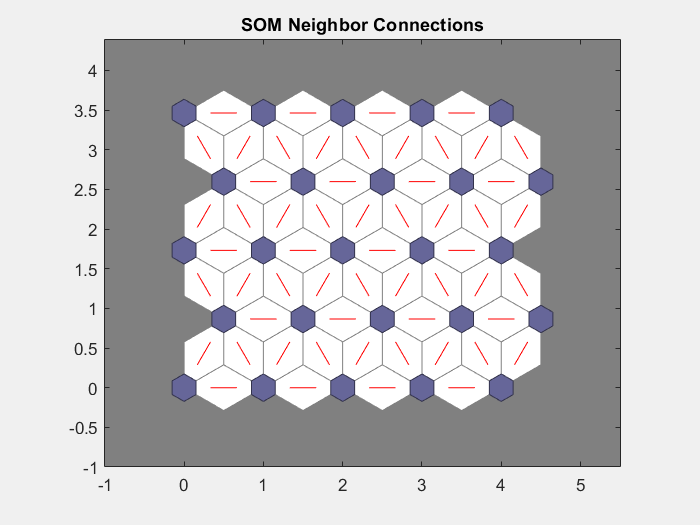

plotsomnc(net);

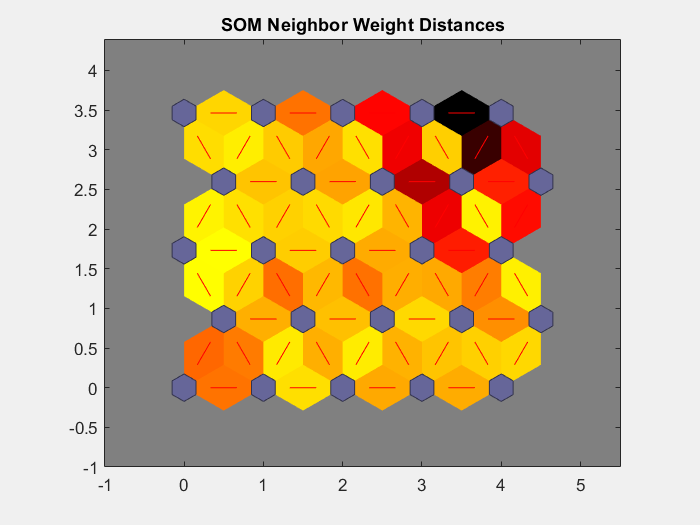

plotsomnd(net);